# ME/SE 701 project

Paper:$H_{\infty }$/LQR Optimal COntrol for a Supersonic Air-Breathing Missile of Asymmetric Configuration

rng(1,'twister');

## Symbol definitions from paper

- Symbol - Discription - Unit - Variable

- $x,y,z$ - Cartesian body axes - m - x_axis,y_axis,z_axis

syms x_axis
syms y_axis 
syms z_axis

- $v,w$ - Translational velocity (y_axis,z_axis respectivly) - m/s - v,w

v = 1;
w = 1;

- $p,q,r$ - Rotational velocity about $x,y,z$ axes - rad/s - p,q,r

p = 0;
q = 0;
r = 0;

- $U$- Constant forward velocity - m/s - U

U = 1029; % mach 3

- $\xi ,\eta ,\zeta$ - Aileron, Elevator and Rudder deflection - radians - xi,eta,zeta

xi   = 0;
eta  = 0;
zeta = 0;

- $\alpha$ - Angle of attack - radians - alpha

alpha = 0; % assume about same axis as q

- $\beta \;$- Sideslip angle - radians - beta

beta = 0; % assume about same axis as r

- $\phi$- Roll angle - radians - phi

phi = 0; % assume about same axis as p

- $a_y ,a_z$ - Accelerations along y ans z axes, respectively - $\frac{m}{s^2 }$ - a_y,a_z

a_y = 0; % assume along the y axis
a_z = 0; % assume along the z axis

- $\gamma$ - Controller performance metric - unitless - gamma

gamma = 0.7585; % given in the paper

- $l_i ,m_i ,n_i$ - partial derivatives of roll, pitch, yaw angular accelerations about i - mixed - l_i,m_i,n_i

-      note for these X = [X_p,X_q,X_r,X_w,X_v,X_xi,X_eta,X_zeta]

L = get_partials([1,10,10,0.01,0.01,2,2,2]);
M = get_partials([1,10,10,0.01,0.01,2,2,2]);
N = get_partials([1,10,10,0.01,0.01,2,2,2]);

- $y_i ,z_i$ - partial derivatives of translational accelerations about i along repective acces -mixed - y_i,z_i

Y = get_partials([1,10,10,100,100,2,2,2]);
Z = get_partials([1,10,10,100,100,2,2,2]);

- Q - LQR gain provided - mixed - Q_provided

Q_provided = diag([1,10,10,0.01,0.01]);

- R - LQR gain provided - mixed - R_provided

R_provided = eye(3)

R_provided =      1     0     0
     0     1     0
     0     0     1


- $W_e \left(S\right)$ - H infinity gain proformance - mixed - W_e

for i = 1:5
    for j = 1:5
        W_e_numd{i,j} = [0];
        W_e_demd{i,j} = [1];
    end
end
%1,1
W_e_numd{1,1} = [1,10];
W_e_demd{1,1} = [2,0.1];
%4,4
W_e_numd{4,4} = [1,4];
W_e_demd{4,4} = [2,0.04];
%5,5
W_e_numd{5,5} = [1,4];
W_e_demd{5,5} = [2,0.04];
% make tf
W_e = tf(W_e_numd,W_e_demd)


W_e =
 
  From input 1 to output...
        s + 10
   1:  ---------
       2 s + 0.1
 
   2:  0
 
   3:  0
 
   4:  0
 
   5:  0
 
  From input 2 to output...
   1:  0
 
   2:  0
 
   3:  0
 
   4:  0
 
   5:  0
 
  From input 3 to output...
   1:  0
 
   2:  0
 
   3:  0
 
   4:  0
 
   5:  0
 
  From input 4 to output...
   1:  0
 
   2:  0
 
   3:  0
 
         s + 4
   4:  ----------
       2 s + 0.04
 
   5:  0
 
  From input 5 to output...
   1:  0
 
   2:  0
 
   3:  0
 
   4:  0
 
         s + 4
   5:  ----------
       2 s + 0.04
 
Continuous-time transfer function.



- $W_u \left(S\right)$ - H infinity gain control - mixed - W_s

for i = 1:3
    for j = 1:3
        W_s_numd{i,j} = [0];
        W_s_demd{i,j} = [1];
    end
end
%1,1
W_s_numd{1,1} = [1,0.009425];
W_s_demd{1,1} = [0.0001,94.25];
%4,4
W_s_numd{2,2} = [1,0.009425];
W_s_demd{2,2} = [0.0001,94.25];
%5,5
W_s_numd{3,3} = [1,0.009425];
W_s_demd{3,3} = [0.0001,94.25];
% make tf
W_s = tf(W_s_numd,W_s_demd)


W_s =
 
  From input 1 to output...
         s + 0.009425
   1:  ----------------
       0.0001 s + 94.25
 
   2:  0
 
   3:  0
 
  From input 2 to output...
   1:  0
 
         s + 0.009425
   2:  ----------------
       0.0001 s + 94.25
 
   3:  0
 
  From input 3 to output...
   1:  0
 
   2:  0
 
         s + 0.009425
   3:  ----------------
       0.0001 s + 94.25
 
Continuous-time transfer function.



## Define LTI system

A = get_A(L,M,N,Y,Z,U,alpha,beta)

A = 	1.0e+03 *

    0.0004    0.0072    0.0000    0.0000    0.0000
    0.0004    0.0054    0.0042    0.0000    0.0000
    0.0004    0.0056    0.0014    0.0000    0.0000
    0.0009    0.0089   -1.0281    0.0039    0.0170
    0.0010    1.0343    0.0069    0.0316    0.0687


B = get_B(L,M,N,Y,Z)

B =     0.1847    0.3725    0.6911
    1.7562    0.0548    1.3409
    1.9365    0.6268    1.3846
    1.7563    0.1967    0.8422
    1.6693    0.0366    1.5003


C = get_C(Y,Z)

C =     1.0000         0         0         0         0
         0    1.0000         0         0         0
         0         0    1.0000         0         0
         0         0         0    3.9055   16.9830
         0         0         0   31.5516   68.6501


D = get_D(Y,Z)

D =          0         0         0
         0         0         0
         0         0         0
    1.7563    0.1967    0.8422
    1.6693    0.0366    1.5003



plant_raw = ss(A,B,C,D);
[plant] = get_plant_model(A,B,C,D)


plant =
 
  A = 
             x_p       x_q       x_r       x_w       x_v
   x_p     0.417     7.203  0.001144  0.003023  0.001468
   x_q    0.3968     5.388     4.192  0.006852  0.002045
   x_r    0.4173     5.587     1.404  0.001981  0.008007
   x_w    0.8764     8.946     -1028     3.905     16.98
   x_v    0.9579      1034     6.919     31.55     68.65
 
  B = 
             xi      eta     zeta
   x_p   0.1847   0.3725   0.6911
   x_q    1.756  0.05478    1.341
   x_r    1.937   0.6268    1.385
   x_w    1.756   0.1967   0.8422
   x_v    1.669  0.03658      1.5
 
  C = 
          x_p    x_q    x_r    x_w    x_v
   p        1      0      0      0      0
   q        0      1      0      0      0
   r        0      0      1      0      0
   ay       0      0      0  3.905  16.98
   az       0      0      0  31.55  68.65
   x_p      1      0      0      0      0
   x_q      0      1      0      0      0
   x_r      0      0      1      0      0
   x_w      0      0      0      1      

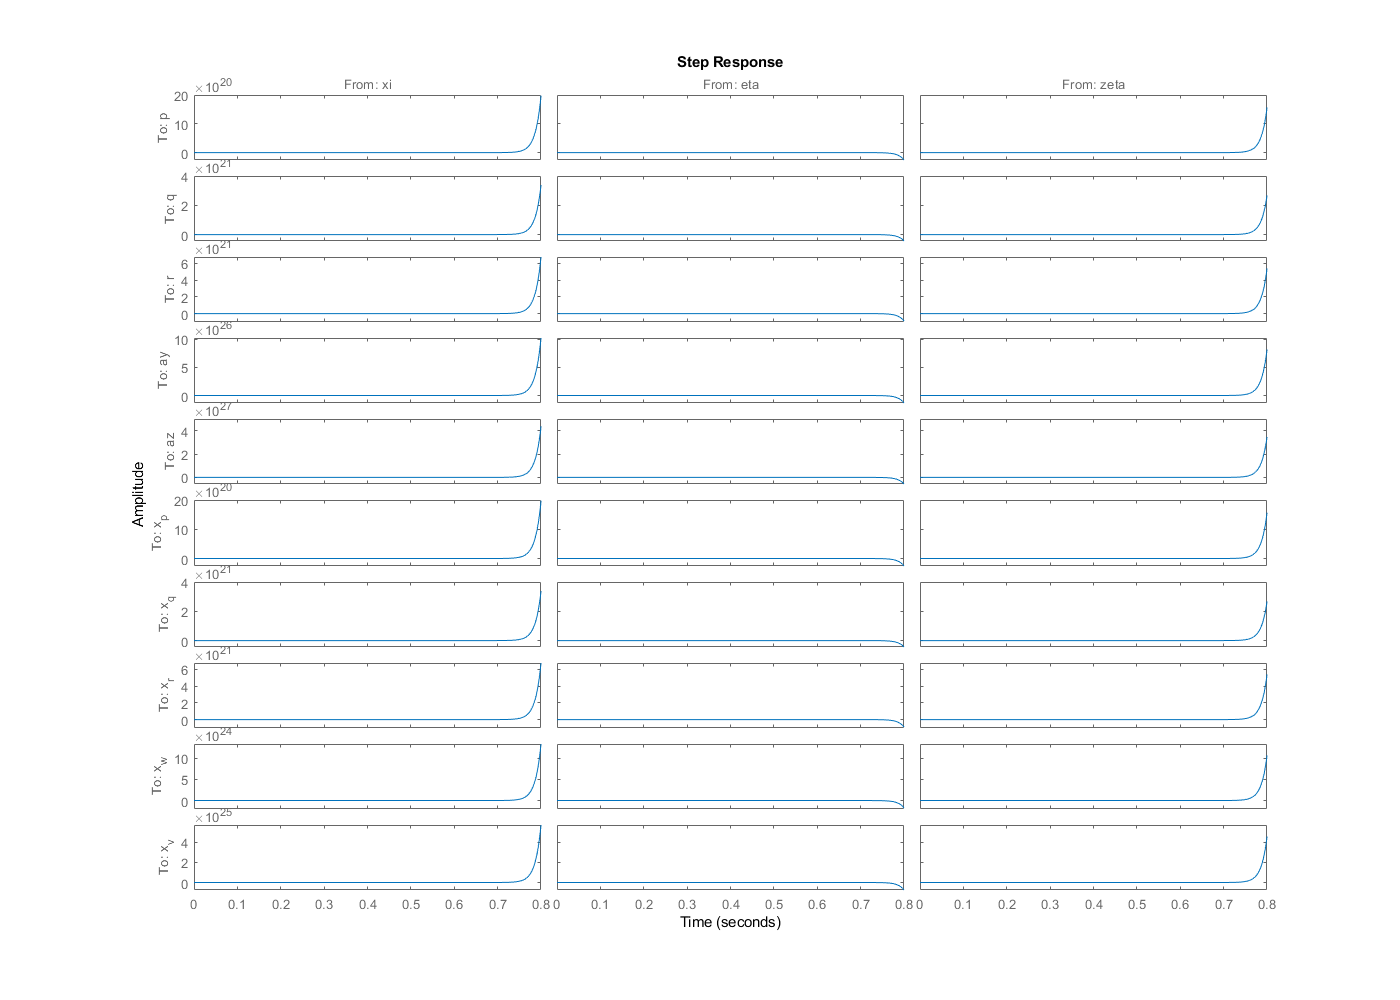

G_plant = tf(plant);
step(plant)

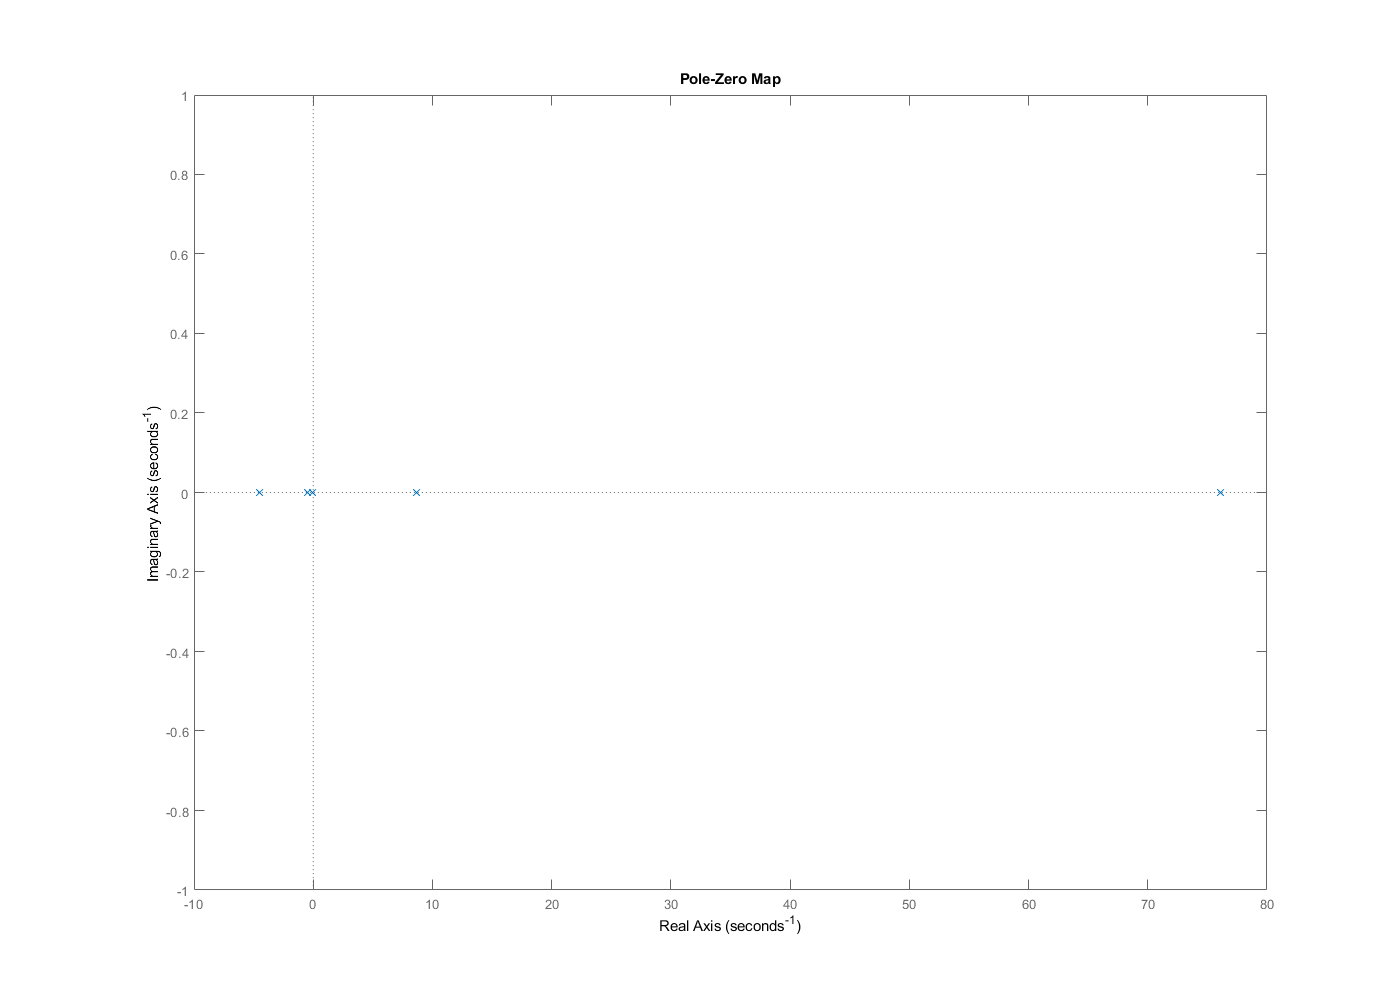

pzplot(plant)

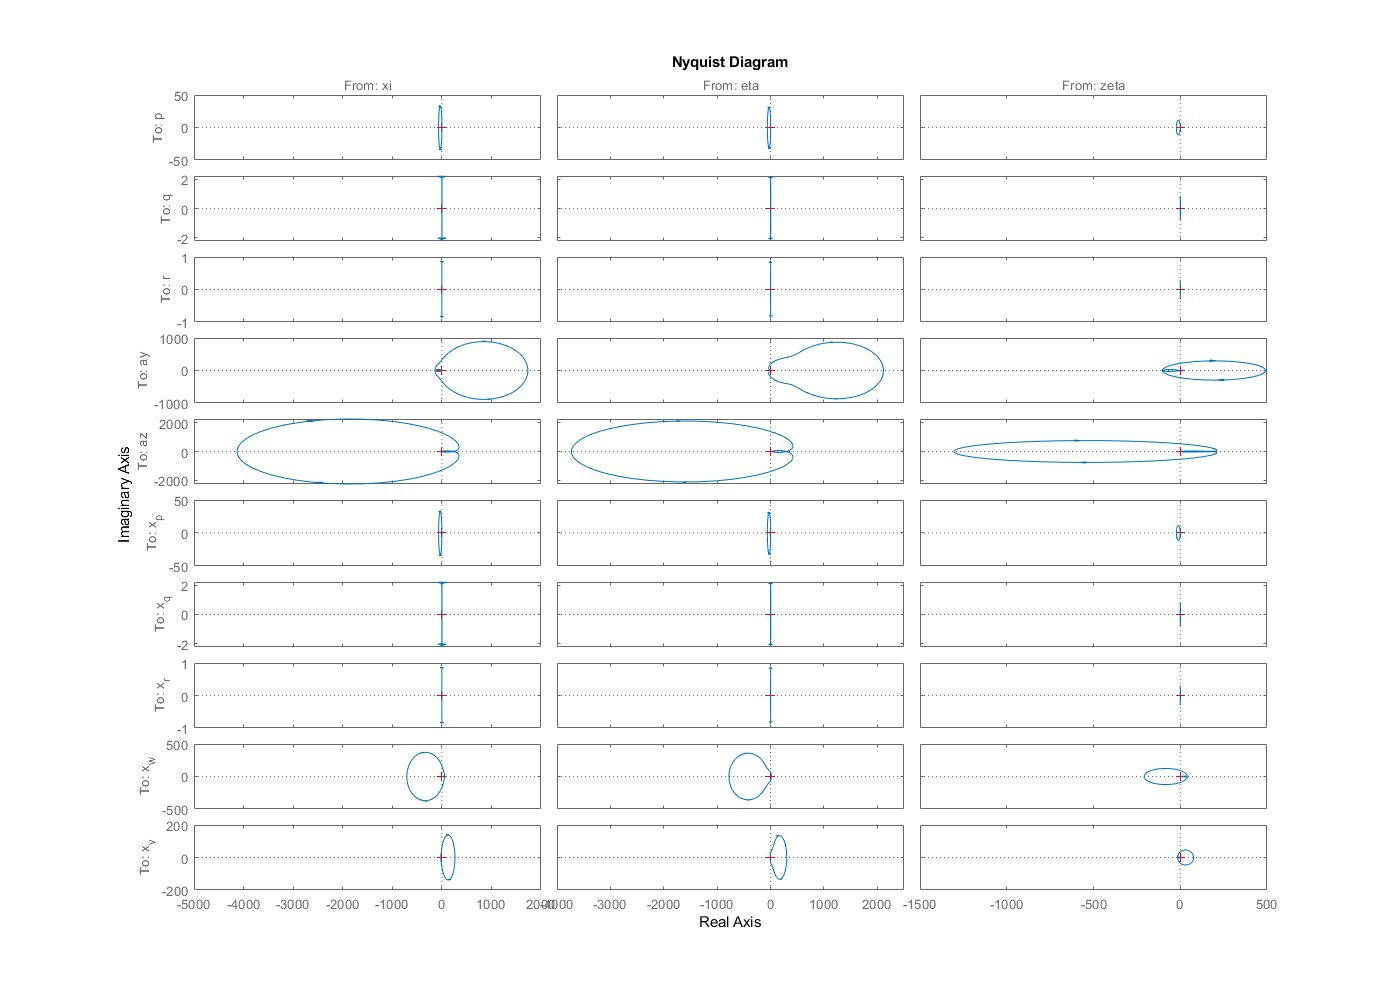

nyquist(plant)

### LQR controler

[K,S,e] = lqr(plant,Q_provided,R_provided,zeros(5,3))

K =    -1.0943   97.2548  -41.6972    3.2921    7.4535
   -0.5537  -30.3229   19.7534   -0.9736   -2.0876
    0.1505   80.7194  -36.4792    2.6702    6.0138


S =     1.4827    1.4288   -1.8704   -0.0397   -0.1113
    1.4288  110.8732  -60.4920    3.5751    7.8699
   -1.8704  -60.4920   38.7434   -1.8987   -4.0774
   -0.0397    3.5751   -1.8987    0.1282    0.2831
   -0.1113    7.8699   -4.0774    0.2831    0.6299


e =   -1.5064 + 0.6432i
  -1.5064 - 0.6432i
 -14.3000 +10.0561i
 -14.3000 -10.0561i
 -76.0504 + 0.0000i



[plant_augment] = get_plant_model(A,B,C,D);
[LQR_control] = get_state_feedback_control(K)


LQR_control =
 
  A = 
         fake
   fake     0
 
  B = 
         x_p  x_q  x_r  x_w  x_v
   fake    0    0    0    0    0
 
  C = 
         fake
   xi       0
   eta      0
   zeta     0
 
  D = 
             x_p      x_q      x_r      x_w      x_v
   xi     -1.094    97.25    -41.7    3.292    7.453
   eta   -0.5537   -30.32    19.75  -0.9736   -2.088
   zeta   0.1505    80.72   -36.48     2.67    6.014
 
Continuous-time state-space model.



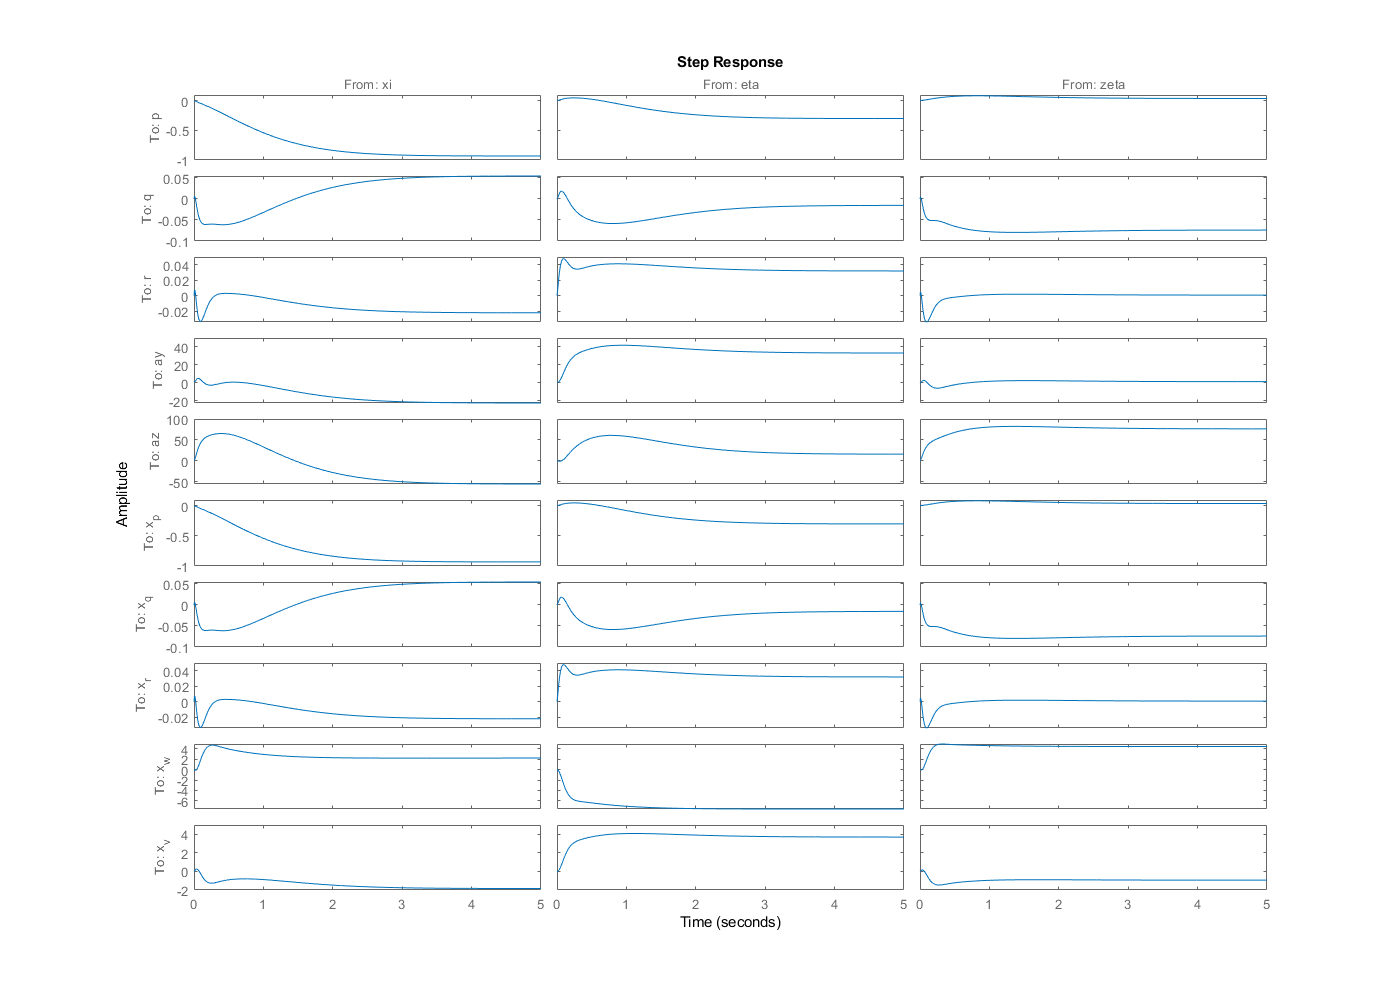

plant_CL = feedback(plant_augment,LQR_control,'name',-1);

step(plant_CL)

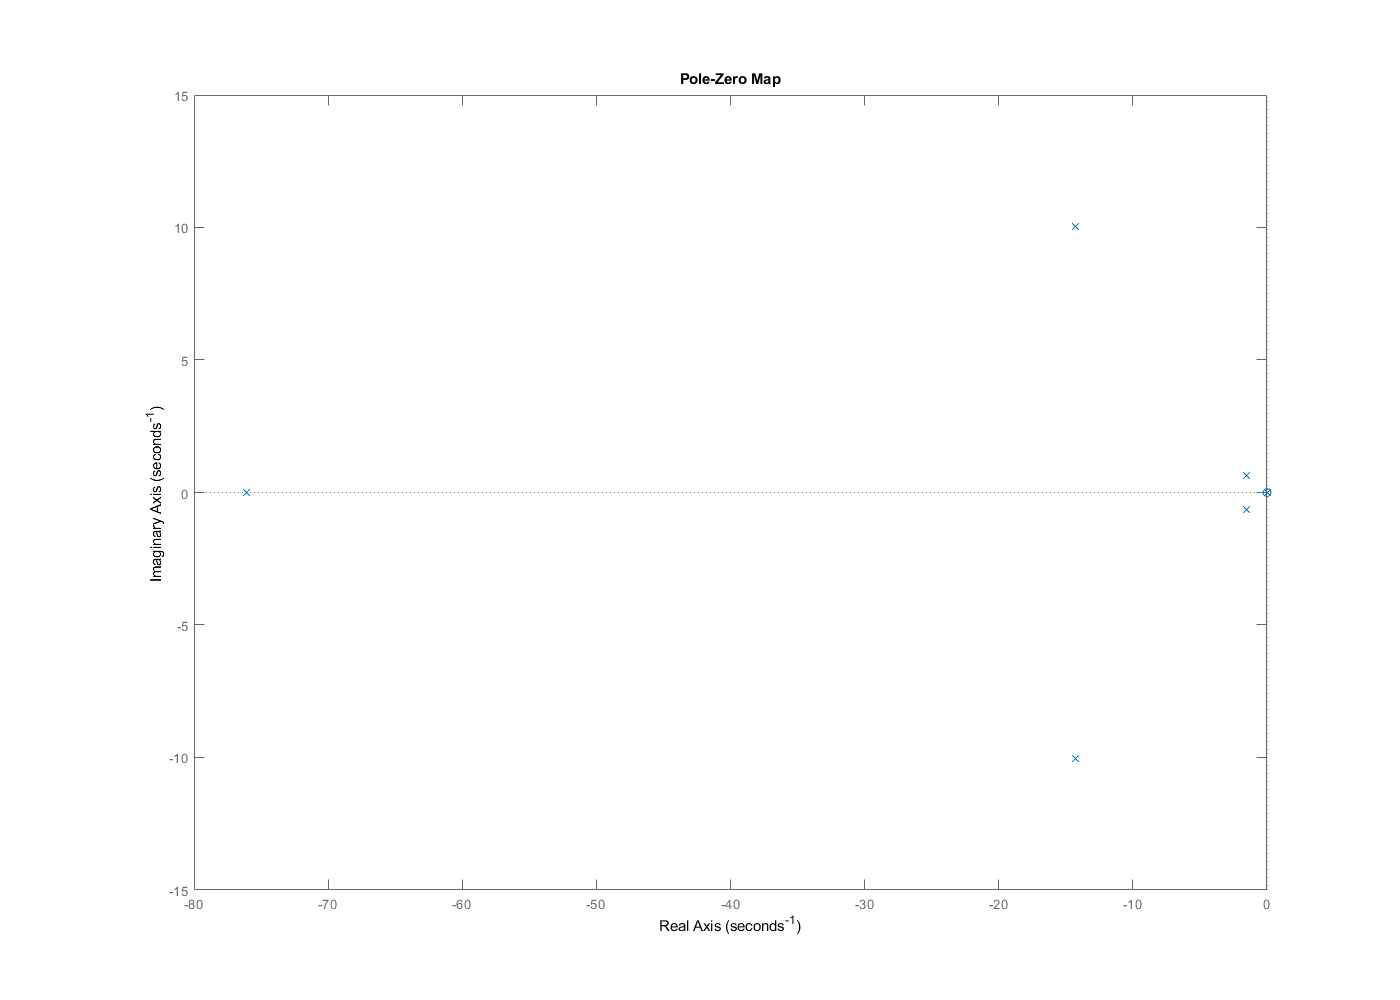

pzplot(plant_CL)

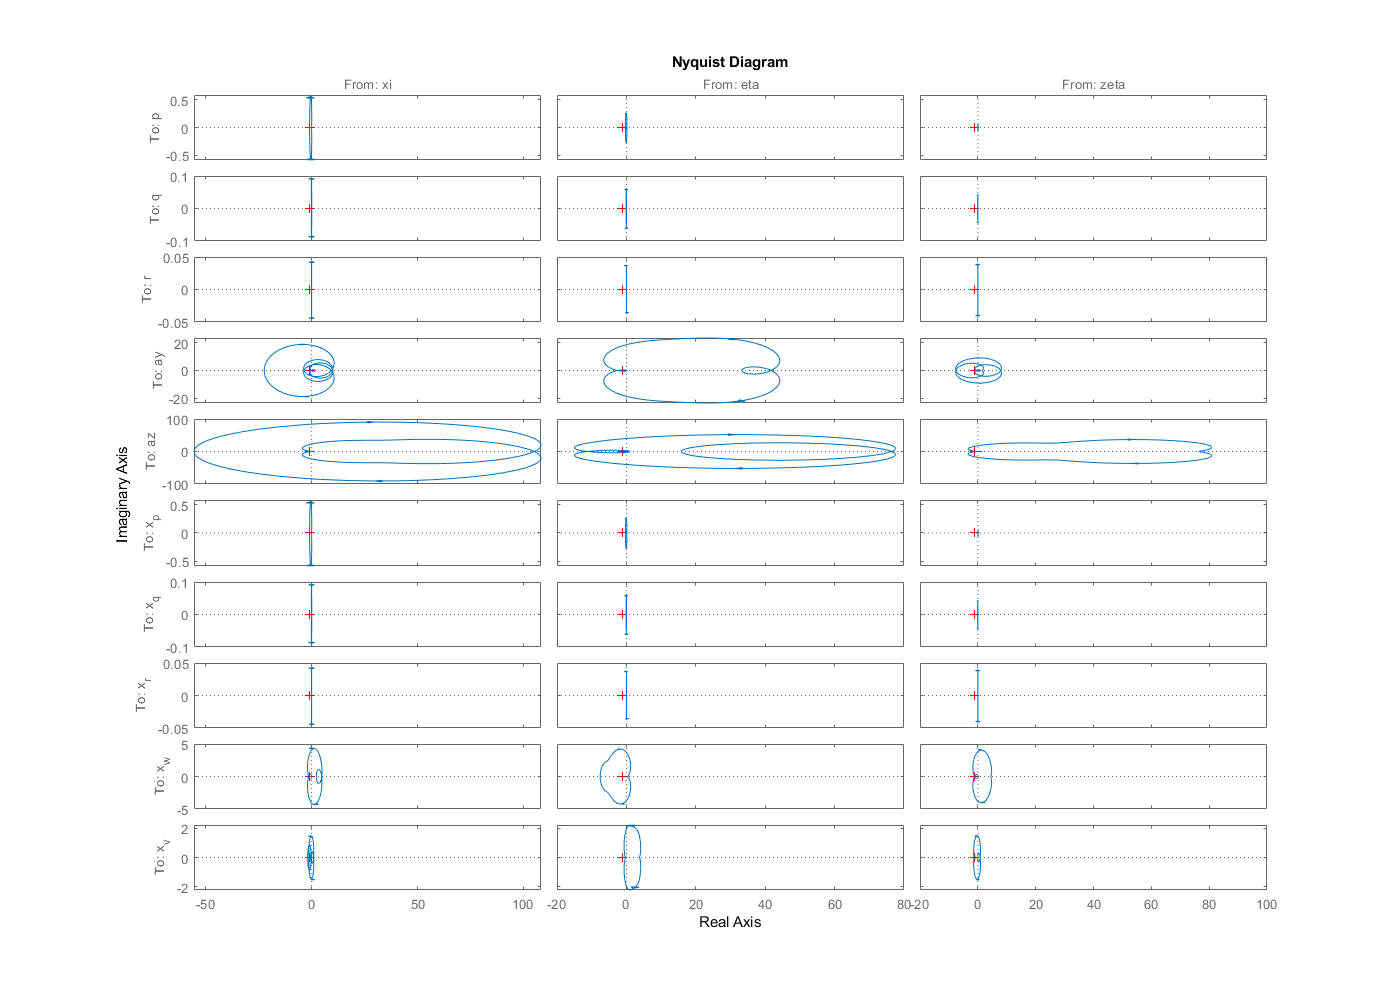

nyquist(plant_CL)

### Hinf

%K_inf = get_Hinf(plant)
G = [A B; C D]

G = 	1.0e+03 *

    0.0004    0.0072    0.0000    0.0000    0.0000    0.0002    0.0004    0.0007
    0.0004    0.0054    0.0042    0.0000    0.0000    0.0018    0.0001    0.0013
    0.0004    0.0056    0.0014    0.0000    0.0000    0.0019    0.0006    0.0014
    0.0009    0.0089   -1.0281    0.0039    0.0170    0.0018    0.0002    0.0008
    0.0010    1.0343    0.0069    0.0316    0.0687    0.0017    0.0000    0.0015
    0.0010         0         0         0         0         0         0         0
         0    0.0010         0         0         0         0         0         0
         0         0    0.0010         0         0         0         0         0
         0         0         0    0.0039    0.0170    0.0018    0.0002    0.0008
         0         0         0    0.0316    0.0687    0.0017    0.0000    0.0015


plantsize = size(G)

plantsize =     10     8


dim = plantsize(:,1)

dim = 10

P = [zeros(dim) eye(dim) G zeros(dim) G; eye(dim) -eye(dim) -G -eye(dim) -G]

P = 	1.0e+03 *

         0         0         0         0         0         0         0         0         0         0    0.0010         0         0         0         0         0         0         0         0         0    0.0004    0.0072    0.0000    0.0000    0.0000    0.0002    0.0004    0.0007         0         0         0         0         0         0         0         0         0         0    0.0004    0.0072    0.0000    0.0000    0.0000    0.0002    0.0004    0.0007
         0         0         0         0         0         0         0         0         0         0         0    0.0010         0         0         0         0         0         0         0         0    0.0004    0.0054    0.0042    0.0000    0.0000    0.0018    0.0001    0.0013         0         0         0         0         0         0         0         0         0         0    0.0004    0.0054    0.0042    0.0000    0.0000    0.0018    0.0001    0.0013
         0         0         0         0         0         0  

### Disterbances

commandError = struct('xi',0.005,'eta',0.005,'zeta',0.005)

commandError = struct with fields:
      xi: 0.0050
     eta: 0.0050
    zeta: 0.0050


disterbance.time = struct('x_p',10,'x_q',20,'x_r',30,'x_w',40,'x_v',50)

disterbance = struct with fields:
         x_p: 0.0500
         x_q: 0.0500
         x_r: 0.0500
         x_w: 0.0500
         x_v: 0.0500
        time: [1×1 struct]
        size: [1×1 struct]
    duration: 5


disterbance.size = struct('x_p',1,'x_q',1,'x_r',1,'x_w',1,'x_v',1)

disterbance = struct with fields:
         x_p: 0.0500
         x_q: 0.0500
         x_r: 0.0500
         x_w: 0.0500
         x_v: 0.0500
        time: [1×1 struct]
        size: [1×1 struct]
    duration: 5


disterbance.duration = 5;
MeasurementNoise = struct('x_p',0.05,'x_q',0.05,'x_r',0.05,'x_w',0.05,'x_v',0.05)

MeasurementNoise = struct with fields:
    x_p: 0.0500
    x_q: 0.0500
    x_r: 0.0500
    x_w: 0.0500
    x_v: 0.0500



VC_Disterbance = 1

VC_Disterbance = 1

VC_Disterbance_Pulse = Simulink.Variant('VC_Disterbance==1')


VC_Disterbance_Pulse =

Simulink.Variant
    Condition: 'VC_Disterbance==1'



VC_Disterbance_Step  = Simulink.Variant('VC_Disterbance==2')


VC_Disterbance_Step =

Simulink.Variant
    Condition: 'VC_Disterbance==2'



- A,B,C,D - state space description - mixed metric standard - A,B,C,D

function A = get_A(L,M,N,Y,Z,U,alpha,beta)
%% creates the A matrix for the BTT missile based on source paper
A = [L(1:5);M(1:5);N(1:5);Y(1:5);Z(1:5)];
A(4,1) = A(4,1) + alpha * U;
A(5,1) = A(5,1) - beta*U;
A(5,2) = A(5,2) + U;
A(4,3) = A(4,3) - U;
end

function B = get_B(L,M,N,Y,Z)
%% creates the B matrix for the BTT missile based on source paper
B = [L(6:8);M(6:8);N(6:8);Y(6:8);Z(6:8)];
end

function C = get_C(Y,Z)
%% creates the C matrix for the BTT missile based on source paper
C = blkdiag(eye(3),[Y(4:5);Z(4:5)]);
end

function D = get_D(Y,Z)
%% creates the D matrix for the BTT misile based on source paper
D = [zeros(3,3);Y(6:8);Z(6:8)];
end

function [Ca,Da] = get_augment_output(C,D)
%% caluclates updated C and D matrixes to chagne the output equation to include the state
    Ca = [C;eye(size(C))];
    Da = [D;zeros(size(C,1),size(D,2))];
end

function [plant] = get_plant_model(A,B,C,D)
    [Ca,Da] = get_augment_output(C,D);
    plant = ss(A,B,Ca,Da);
    plant.InputName = {'xi','eta','zeta'};
    plant.OutputName = {'p','q','r','ay','az','x_p','x_q','x_r','x_w','x_v'};
    plant.StateName = {'x_p','x_q','x_r','x_w','x_v'};
end

function [controller] = get_state_feedback_control(K)
    controller = ss(0,zeros(1,5),zeros(3,1),K);
    controller.InputName = {'x_p','x_q','x_r','x_w','x_v'};
    controller.StateName = {'fake'};
    controller.OutputName = {'xi','eta','zeta'};
end

- X - state vector ${\left\lbrack p,q,r,w,v\right\rbrack }^T$ - mixed metric standard - x

function x = get_x(p,q,r,w,v)
    x=[p,q,r,w,v]';
end

- u - control vector ${\left\lbrack \xi \;,\eta \;,\zeta \right\rbrack }^T$ - mixed metric standard - u

function u = get_u(xi,eta,zeta)
    u=[xi,eta,zeta]';
end

- $K_s$ - LQR gain - mixed - K_s

function K_s = get_K_s(R,B,Ricatti)
    K_s = inv(R)*B'*Ricatti;
end

- $K_p$ - $H_{\infty }$ gain - mixed - K_p

- $P\left(s\right)$ - state space realisation of general plant - mixed - P_a

## Get partial derivative array

X = [X_p,X_q,X_r,X_w,X_v,X_xi,X_eta,X_zeta]

function dxdx = get_partials(scaleing)
% about rotational velocities
X_p = rand(1)*scaleing(1);
X_q = rand(1)*scaleing(2);
X_r = rand(1)*scaleing(3);
% about translational velocities
X_w = rand(1)*scaleing(4);
X_v = rand(1)*scaleing(5);
% about control inputs
X_xi = rand(1)*scaleing(6);
X_eta = rand(1)*scaleing(7);
X_zeta = rand(1)*scaleing(8);
dxdx =  [X_p,X_q,X_r,X_w,X_v,X_xi,X_eta,X_zeta];
end

### Perturbed Plant

function delta_plant = get_perturbed_plant(plant,A_scale,B_scale,A_rot_xyz)
A = plant.A .* A_scale;
B = plant.B .* B_scale;

A = A*rotx(A_rot_xyz(1))*roty(A_rot_xyz(2))*rotz(A_rot_xyz(3));

delta_plant = plant;
delta_plant.A = A;
delta_plant.B = B;
end


### Evaluate CL plant

function report = test_plant(plant)

report.stepinfo = stepinfo(plant);
try
    report.HistSettlingTime = histogram(report.stepinfo.SettlingTime);
catch ME
    report.HistSettlingTime = ME.message;
end
report.nyquistPlot = nyquist(plant);
[p,z]=pzmap(plant);
report.systemPoles = p;
report.systemZeros = z;

end